# Transfer Function · 학습

## 실행 조건

MATLAB · Control System Toolbox

## 이번에 배울 내용

같은 계수라도 연결 방식이나 상쇄 조건에 따라 응답이 달라집니다. 계수에서 동작을 예측하는 연습입니다.

## 전체 흐름

계수 배열 → Transfer Function → Pole·Zero → Step 응답

## 계수 배열을 Transfer Function으로 읽기

- 계수 배열: 차수가 높은 항부터.

- `num=[2]`, `den=[5,1]`: $H(s)=2/(5s+1)$.

- Pole: 분모의 근. 이 예에서는 $-0.2$.

- Zero: 분자의 근. 이 예에서는 유한 Zero 없음.

- DC Gain: $H(0)=2$. 분모의 상수항이 0이 아닙니다.

## Pole과 실제 응답 연결하기

음의 실수 Pole −0.2에 대응하는 exp(−0.2t)의 Time Constant는 5초입니다. 계수로 구한 근과 Time Response를 함께 보면 계산이 물리적으로 무엇을 뜻하는지 확인할 수 있습니다.

직렬은 곱, 병렬은 합이며, 음의 단위 Feedback은 H/(1+H)로 분모까지 바꿉니다.

## 공통 인자의 상쇄

(s+2)/((s+1)(s+2))는 상쇄 후 1/(s+1)로 나타낼 수 있습니다. 분자의 2가 2.1로 바뀌면 완전한 상쇄가 아닙니다. 모델의 차수와 응답의 작은 차이를 함께 확인합니다.

## 계수에서 Pole·응답까지

H(s)=1/(2s+1)의 Pole은 −0.5, DC Gain은 1, Time Constant는 2초입니다. 아래에서 식과 그래프를 함께 확인합니다.

%% Worked example
s=tf('s'); H=1/(2*s+1); t=linspace(0,10,501)';
disp('Pole / Zero / DC Gain'); disp(pole(H)); disp(zero(H)); disp(dcgain(H));

Pole / Zero / DC Gain
   -0.5000

     1



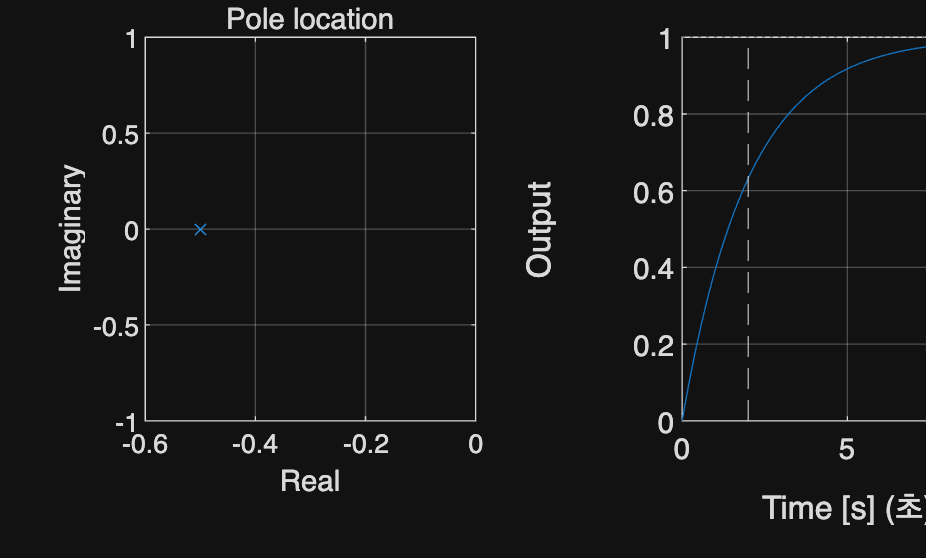

figure; tiledlayout(1,2);
nexttile; plot(-.5,0,'x'); xline(0); xlabel('Real'); ylabel('Imaginary'); title('Pole location'); grid on
nexttile; step(H,t); xline(2,'--'); xlabel('Time [s]'); ylabel('Output'); title('Unit step'); grid on

## 참고 예제

추가 예제 보기

[참고 자료](https://chorok-daddy.github.io/niil/courses/control-2/transfer-functions/index.html)